Consider the confound of scanner manufacture.

scanner: similarity of scanner manufacture between sites

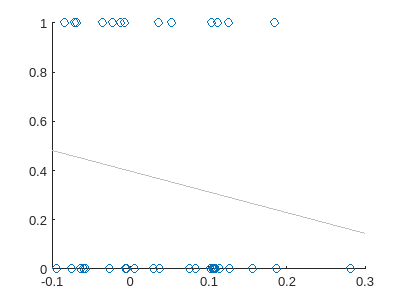

BD


                     scanner 
                     ________

    spearman corr    -0.15866
    p                 0.16762



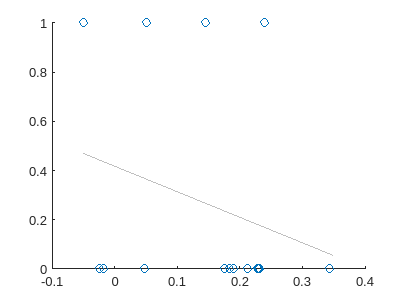

SCA


                     scanner 
                     ________

    spearman corr    -0.20936
    p                 0.23054



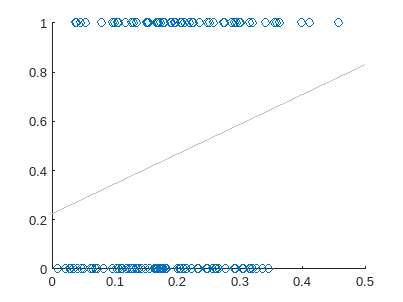

SCZ


                     scanner 
                     ________

    spearman corr     0.21473
    p                0.074131



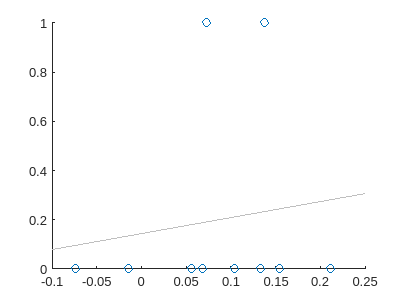

ASD


                     scanner
                     _______

    spearman corr    0.17408
    p                0.31913



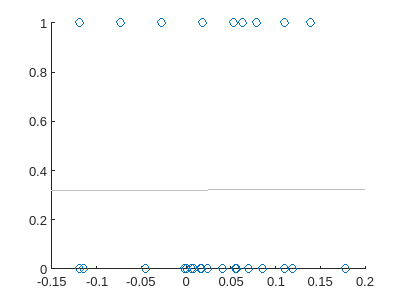

MDD


                     scanner 
                     ________

    spearman corr    0.052068
    p                    0.38



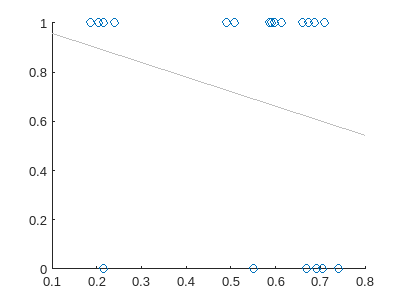

AD


                     scanner 
                     ________

    spearman corr    -0.34816
    p                0.071767



% Clear all variables and close all figures
clear all
close all

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is used
smoothKernel = 6; % Smoothing kernel size
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Correlation type (Spearman)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata containing scanner information
metadata = readtable(['/projects/kg98/trangc/VBM/data/scanner_site_detailed.csv'], 'VariableNamingRule', 'preserve');

% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '.mat'], ...
     'cor1', 'cor2', 'siteList');

% Loop through each diagnosis
for iDiag = 1:nDiag
   
    % Compute variance related to scanner manufacture similarity
    [varTable{iDiag}, nSite{iDiag}] = cor_var_scanner(metadata, ...
        diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag}, siteList{iDiag},iter, type);
    
    % Display results if the variance table is not empty
    if size(varTable, 1) ~= 0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ');
    end
end


% Suppress specific warnings and save the results
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_scanner.mat', 'varTable', 'nSite');
